Ejemplos revision

clear
%%Case 1
%%Buck Converter, Voltage drop, from 50 to 25V
%
L_1=100e-03; %Coil
C=1000e-06; %Capacitor
R=10; %Resistance
T=0.01; %Discretization period
V=200; %V_input
time=0.2;%Duration of the control action simmulation
A=[0 -1/L_1; 1/C -1/R/C]; %State matrix "Buck Converter"
B=[V/L_1; 0]; %Input matrix
V_o=50;
I_o=3.2619; 
V_f=25;
lambda=0.8;




$$x_f=PA x_f+PB \Delta_f$$



$$(I-PA)x_f =PB\Delta_f$$



$$x_f=(I-PA)^{-1}PB\Delta_f$$


Al reves


$$y_f=C(I-PA)^{-1}PB\Delta_f$$



$$\Delta_f=(C(I-PA)^{-1}PB)^{-1}y_f$$


Discretizamos el sistema

[PA,PB,alpha2]=discrete_binary_f(A,B,T)

PA =     0.6597   -0.0534
    5.3351    0.1262


PB =   2 MDCHP array with properties:

    grado: [1 1]
    n_var: [2 2]
     coef: {[2×1 double]  [2×1 double]  [2×1 double]  [2×1 double]}


alpha2 = 2×1 cell array
    {@(delta)(f_1(delta)-f_min)/(f_max-f_min)}
    {                           @(x)alpha1(x)}


delta=V_f/V;
alpha=[]


alpha =

     []



r=rank(A)

r = 2

for j=1:length(alpha2)
    i=ceil(j/r);    
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end
Balpha=PB.eval(alpha)

Balpha =    13.8532
  104.7718


x_f=inv(eye(length(A))-PA)*Balpha*delta

x_f =     1.3994
   23.5319


delta_f=inv([0 1]*(inv(eye(length(A))-PA)*Balpha))*V_f

delta_f = 0.1328

aux=0;
delta_ant=-1;
while (aux<30)&&(abs(delta-delta_ant)>1e-6)
    aux=aux+1;
    delta_ant=delta;
    alpha=[];
    for j=1:r
        alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
    end
    Balpha=PB.eval(alpha);
    delta=inv([0 1]*(inv(eye(length(A))-PA)*Balpha))*V_f;
    delta=(delta+delta_ant)/2;
end
delta

delta = 0.1326

aux

aux = 13

alpha=[]


alpha =

     []



for j=1:length(alpha2)
    i=ceil(j/r);
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end
Balpha=PB.eval(alpha);
x_f=inv(eye(length(A))-PA)*Balpha*delta

x_f =     1.4941
   24.9999


delta_f=delta

delta_f = 0.1326

Simulación

Td=T/1000;
N=1000*(time/T);
x=zeros(2,N);
x(:,1)=[I_o;V_o];
u=[];
for i=1:N+1
    if (mod(i,1000)/1000<delta)
       x(:,i+1)=x(:,i)+Td*(A*x(:,i)+B);
       u=[u 1];
    else
       x(:,i+1)=x(:,i)+ Td*A*x(:,i);
       u= [u 0];
    end
    if (x(1,i+1)<0)
        x(1,i+1)=0;
    end
end
t=[0 (1:N+1)*Td];

Discrete model

N=0.2/0.01; %Number of cycles
x2=zeros(length(A),N);
x2(:,1)=[I_o,V_o]'; %Initial state
alpha=[];
r=rank(A);
for j=1:length(alpha2)
    i=ceil(j/r);
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end
%Calculates each X value for each period of time.
for i=1:N+1
    x2(:,i+1)=PA*x2(:,i)+PB.eval(alpha)*delta';
end
t2=[0 (1:N+1)*T];
figure
plot(t,x') 
hold on
plot(t2,x2','x')
hold off
%title('Discret response VS. continuous response:')


Average model

N=1000*(time/T);
A_avg=[0 -1/L_1; 1/C -1/R/C];
B_avg=[V/L_1; 0];
x_avg=zeros(2,N);
x_avg(:,1)=[I_o;V_o];
delta=V_f/V

delta = 0.1250

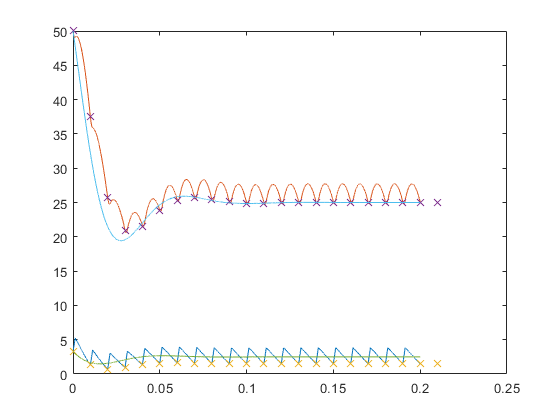

for i=1:N+1
    x_avg(:,i+1)=x_avg(:,i)+Td*(A_avg*x_avg(:,i)+B_avg*delta);
    if (x_avg(1,i+1)<0)
        x_avg(1,i+1)=0;
    end
end
hold on
t_avg=[0 (1:N+1)*Td];
plot(t_avg,x_avg')

AVG=ss(A_avg,B_avg,[0,1],0);
Hd=c2d(AVG,T);
[Ad,Bd,Cd,Dd] = ssdata(Hd);
x_avgf=inv(eye(length(Ad))-Ad)*Bd*delta;
delta_avgf=delta;

Diseño controlador borroso

%Controller design 1, no input limit, no decay rate.
[V,D]=eig(A);
r=rank(A);
n=length(D);
%%LMI optimization:
X1=sdpvar(n);
LMI1=[X1>=1e-8];
for i=1:PB.num_coef
    M1{i}=sdpvar(1,n);
end
PM1=MDCHP(ones(1,n),2*ones(1,n),M1);
PQR1=[lambda^2*X1 X1*PA'+PM1'*PB';PA*X1+PB*PM1 X1];
PQR1.Polya([4 4 4 4]);
coef1=PQR1.coef;
for i=1:length(coef1)
    LMI1=[LMI1 coef1{i}>=1e-8];
end
optimize(LMI1);

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 11, order n = 103, dim = 405, blocks = 27
nnz(A) = 609 + 0, nnz(ADA) = 121, nnz(L) = 66
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.35E+01 0.000
  1 :   0.00E+00 1.48E+01 0.000 0.2012 0.9000 0.9000   1.00  1  1  1.7E+01
  2 :   0.00E+00 6.87E-01 0.000 0.0465 0.9900 0.9900   1.00  1  1  8.0E-01
  3 :   0.00E+00 3.11E-04 0.000 0.0005 0.9999 0.9999   1.00  1  1  3.6E-04
  4 :   0.00E+00 3.12E-11 0.000 0.0000 1.0000 1.0000   1.00  1  1  3.6E-11

iter seconds digits       c*x               b*y
  4      0.2   7.8 -1.6367647944e-18  0.0000000000e+00
|Ax-b| =   2.5e-11, [Ay-c]_+ =   0.0E+00, |x|=  2.8e-11, |y|=  1.7e+00

Detailed timing (sec)
   Pre          IPM          Post
4.600E-02    1.010E-01    9.998E-03    
Max-norms: ||b||=0, ||c|| = 2.000000e-08,
Cholesky |add|=0, |skip| = 0, ||L.L|| = 11.1206.


K1=double(PM1)*inv(double(X1));

% busco el valor de decay rate que hemos conseguido
alpha_2=sdpvar(1);
LMItest=[alpha_2>=1e-8];
P=inv(double(X1));
PQR2=(PA+PB*K1)'*P*(PA+PB*K1)-alpha_2*P;
PQR2.Polya([4 4 4 4]);
coef2=PQR2.coef;
for i=1:length(coef2)
    LMItest=[LMItest coef2{i}<=-1e-8];
end
optimize(LMItest,alpha_2)

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 1, order n = 52, dim = 102, blocks = 26
nnz(A) = 76 + 0, nnz(ADA) = 1, nnz(L) = 1
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.00E+01 0.000
  1 :  -9.60E-01 1.71E+01 0.000 0.3429 0.9000 0.9000   1.06  1  1  2.4E+01
  2 :  -5.57E-01 3.61E+00 0.000 0.2107 0.9000 0.9000   2.88  1  1  2.0E+00
  3 :  -5.12E-01 1.51E+00 0.000 0.4192 0.9000 0.9000   1.51  1  1  7.5E-01
  4 :  -5.25E-01 4.20E-01 0.000 0.2776 0.9000 0.9000   1.06  1  1  2.1E-01
  5 :  -5.22E-01 2.23E-03 0.000 0.0053 0.9990 0.9990   1.03  1  1  1.1E-03
  6 :  -5.22E-01 1.02E-05 0.000 0.0046 0.9990 0.9990   1.00  1  1  5.0E-06
  7 :  -5.22E-01 2.61E-07 0.000 0.0255 0.9900 0.9900   1.00  1  1  1.3E-07
  8 :  -5.22E-01 1.98E-08 0.207 0.0761 0.9900 0.9900   1.00  1  1  9.7E-09
  9 :  -5.22E-01 1.35E-09 0.000 0.0682 0.9900 0.9900   1.00  1  1  6.6E-10

iter seconds digit

ans = struct with fields:
    yalmipversion: '20190425'
       yalmiptime: 0.1438
       solvertime: 0.1612
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


sqrt(double(alpha_2))

ans = 0.7227

Simulacion control borroso X3

x3=zeros(n,time/T);
x3(:,1)=[I_o,V_o]';
t3=[0 (1:length(x3))*T];
muT3=[];
alpha_sat1=[];
alpha_sat2=[];
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
for i=1:length(x3)
    Ki=K1*(x3(:,i)-x_f)+delta_f;
    aux=0;
    delta=sum(Ki.array())/Ki.num_coef();
    delta=delta*(delta<1)*(delta>0)+(delta>1);
    delta_ant=-1;
    while (aux<20)&&(abs(delta-delta_ant)>1e-6);
        aux=aux+1;
        delta_ant=delta;
        alpha=[];
        for j=1:r
           alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
        end
        delta=Ki.eval(alpha);
        delta=(delta+delta_ant)/2;
    end
    aux;
    delta;
    alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        alpha=alpha_sat1;
    end
    muT3=[muT3 delta];
    x3(:,i+1)=PA*x3(:,i)+PB.eval(alpha)*delta;
end
figure
plot(t3,x3','o')

Simulación controlador borroso sistema continuo

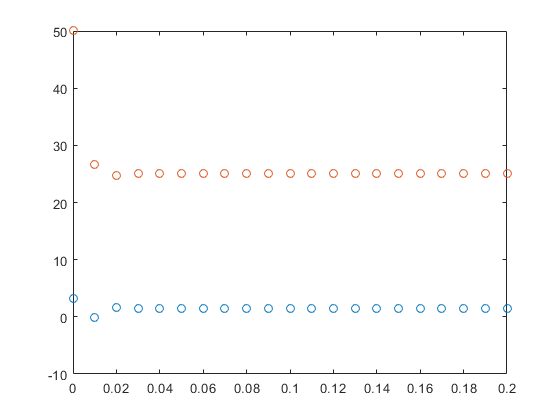

muT3=[];
alpha_sat1=[];
alpha_sat2=[];
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
Td=T/1000;
N=1000*(time/T);
t3c=[0 (1:N)*Td];
x3c=zeros(n,N);
x3c(:,1)=[I_o;V_o];
delta=0.125;
x=zeros(2,N);


for i=1:N
    if (mod(i,1000)==0)||(i==1)
        Ki=K1*(x3c(:,i)-x_f)+delta_f;
        aux=0;
        delta=sum(Ki.array())/Ki.num_coef();
        delta=delta*(delta<1)*(delta>0)+(delta>1);
        delta_ant=-1;
        while (aux<30)&&(abs(delta-delta_ant)>1e-6)
            aux=aux+1;
            delta_ant=delta;
            alpha=[];
            for j=1:r
                alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
            end
            delta=Ki.eval(alpha);
            delta=(delta+delta_ant)/2;
        end
        aux;
        muT3=[muT3 delta];
    end
    
    delta;
    alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        alpha=alpha_sat1;
    end
    if (mod(i,1000)/1000<delta)
       x3c(:,i+1)=x3c(:,i)+Td*(A*x3c(:,i)+B);
    else
       x3c(:,i+1)=x3c(:,i)+ Td*A*x3c(:,i);
    end
    if (x3c(1,i+1)<0)
        x3c(1,i+1)=0;
    end
    
    %x3(:,i+1)=PA*x3(:,i)+PB.eval(alpha)*delta;    
end
hold off

plot(t3c,x3c(2,:)','b')
hold on
plot(t3,x3(2,:)','bo')

Controlador para AVG

[V,D]=eig(Ad);
r=rank(Ad);
n=length(D);

%%LMI optimization:
X5=sdpvar(n);
LMI5=[X5>=1e-8];
M5=sdpvar(1,n);
PQR5=[lambda^2*X5 X5*Ad'+M5'*Bd';Ad*X5+Bd*M5 X5];
LMI5=[LMI5 PQR5>=1e-8];
%LMI5=[ LMI5 [1 x0';x0 X5]>=1e-8];
%LMI5=[LMI5, [X5 M5';M5 1e6]>=1e-8]; 
optimize(LMI5);

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 5, order n = 7, dim = 21, blocks = 3
nnz(A) = 21 + 0, nnz(ADA) = 25, nnz(L) = 15
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.79E+00 0.000
  1 :   0.00E+00 6.87E-01 0.000 0.0701 0.9900 0.9900   1.00  1  1  5.1E-01
  2 :   0.00E+00 2.34E-02 0.000 0.0340 0.9900 0.9900   1.00  1  1  1.7E-02
  3 :   0.00E+00 7.04E-07 0.000 0.0000 1.0000 1.0000   1.00  1  1  5.2E-07
  4 :   0.00E+00 7.10E-14 0.000 0.0000 1.0000 1.0000   1.00  1  1  5.3E-14

iter seconds digits       c*x               b*y
  4      0.0  10.6 -2.8145186178e-21  0.0000000000e+00
|Ax-b| =   2.8e-14, [Ay-c]_+ =   0.0E+00, |x|=  1.2e-13, |y|=  1.6e+00

Detailed timing (sec)
   Pre          IPM          Post
7.996E-03    2.001E-02    3.993E-03    
Max-norms: ||b||=0, ||c|| = 2.000000e-08,
Cholesky |add|=0, |skip| = 0, ||L.L|| = 12.7926.


K5=double(M5)*inv(double(X5));

alpha_3=sdpvar(1);
LMItest=[alpha_3>=1e-8];
P=inv(double(X5));
LMItest=[LMItest (Ad+Bd*K5)'*P*(Ad+Bd*K5)-alpha_3*P<=-1e-8];
optimize(LMItest,alpha_3)

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 1, order n = 4, dim = 6, blocks = 2
nnz(A) = 4 + 0, nnz(ADA) = 1, nnz(L) = 1
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.54E+00 0.000
  1 :  -5.20E-01 2.04E+00 0.000 0.2709 0.9000 0.9000   1.68  1  1  1.5E+00
  2 :  -3.82E-01 5.46E-01 0.000 0.2673 0.9000 0.9000   1.78  1  1  3.0E-01
  3 :  -4.18E-01 4.08E-03 0.000 0.0075 0.9990 0.9990   1.03  1  1  2.0E-03
  4 :  -4.18E-01 8.69E-07 0.000 0.0002 0.9999 0.9999   1.00  1  1  4.3E-07
  5 :  -4.18E-01 2.07E-07 0.000 0.2380 0.9000 0.9000   1.00  1  1  1.0E-07
  6 :  -4.18E-01 1.26E-08 0.000 0.0607 0.9900 0.9900   1.00  1  1  6.8E-09
  7 :  -4.18E-01 2.33E-09 0.000 0.1858 0.9000 0.9000   1.00  1  1  1.3E-09
  8 :  -4.18E-01 5.83E-10 0.000 0.2498 0.9000 0.9000   1.00  1  1  3.2E-10

iter seconds digits       c*x               b*y
  8      0.1  10.3 -4.1785363021e-01 -4.1785363023

ans = struct with fields:
    yalmipversion: '20190425'
       yalmiptime: 0.1100
       solvertime: 0.0540
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


sqrt(double(alpha_3))

ans = 0.6464


% ideas para aumentar alpha3 a 0.77 como alpha2
K6=place(Ad,Bd,[0.999 0.998])

K6 =    -0.0816    0.0032


P=sdpvar(2);
LMItest=[P>=1e-8];
LMItest=[LMItest (Ad+Bd*K6)'*P*(Ad+Bd*K6)-0.77^2*P<=-1e-8];
optimize(LMItest)

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 5, dim = 9, blocks = 3
nnz(A) = 12 + 0, nnz(ADA) = 9, nnz(L) = 6
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.86E+00 0.000
  1 :   0.00E+00 6.45E-01 0.000 0.0941 0.9900 0.9900   1.00  1  1  4.6E-01
  2 :   0.00E+00 4.19E-02 0.000 0.0650 0.9900 0.9900   1.00  1  1  3.0E-02
  3 :   0.00E+00 7.70E-03 0.000 0.1837 0.9000 0.9000   1.00  1  1  5.5E-03
  4 :   0.00E+00 5.26E-06 0.000 0.0007 0.9999 0.9999   1.00  1  1  3.7E-06
  5 :   0.00E+00 5.28E-13 0.000 0.0000 1.0000 1.0000   1.00  1  1  3.7E-13

iter seconds digits       c*x               b*y
  5      0.1   8.8 -1.7458714169e-19  0.0000000000e+00
|Ax-b| =   1.4e-13, [Ay-c]_+ =   0.0E+00, |x|=  1.3e-11, |y|=  2.5e+00

Detailed timing (sec)
   Pre          IPM          Post
7.001E-03    3.100E-02    2.997E-03    
Max-norms: ||b||=0, ||c|| = 2.000000e-08,
Cholesky 

ans = struct with fields:
    yalmipversion: '20190425'
       yalmiptime: 0.1286
       solvertime: 0.0454
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


Simulacion AVG

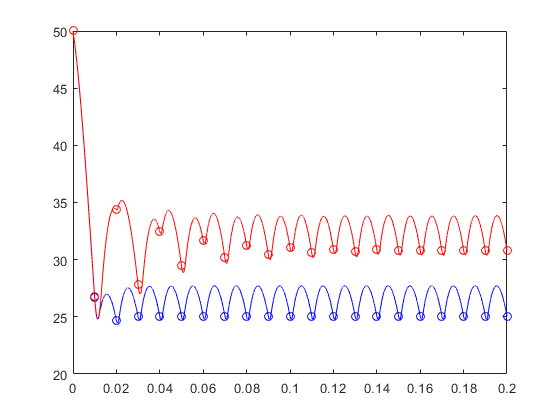

alpha_sat1=[];
alpha_sat2=[];
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
Td=T/1000;
N=1000*(time/T);
t7c=[0 (1:N)*Td];
x7c=zeros(n,N);
x7c(:,1)=[I_o;V_o];

x=zeros(2,N);

x7=[];
muT7c=[];
for i=1:N
    if (mod(i,1000)==0)||(i==1)
        delta=K5*(x7c(:,i)-x_avgf)+delta_avgf;
        x7=[x7 x7c(:,i)];
        if (delta>=1)||(isnan(delta))
            delta=1;
        elseif delta<0
            delta=0;
        end
        muT7c=[muT7c delta];        
    end
    
    delta;
    alpha;
    
    if (mod(i,1000)/1000<(delta))
       x7c(:,i+1)=x7c(:,i)+Td*(A*x7c(:,i)+B);
    else
       x7c(:,i+1)=x7c(:,i)+ Td*A*x7c(:,i);
    end
    if (x7c(1,i+1)<0)
        x7c(1,i+1)=0;
    end
    %muT3=[muT3 delta];
    %x3(:,i+1)=PA*x3(:,i)+PB.eval(alpha)*delta;    
end
hold on
plot(t7c,x7c(2,:)','r')
plot(t3,x7(2,:)','ro')


hold off

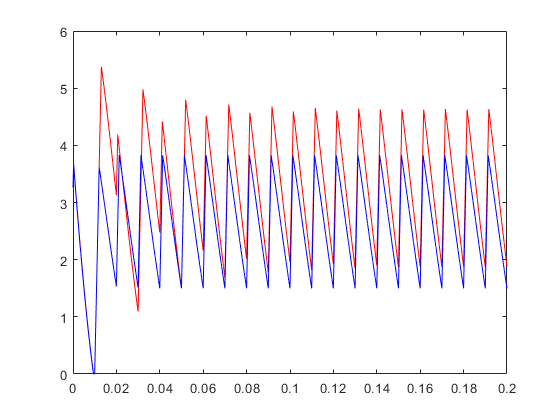

plot(t7c,x7c(1,:)','r')
hold on
plot(t3c,x3c(1,:)','b')
hold off

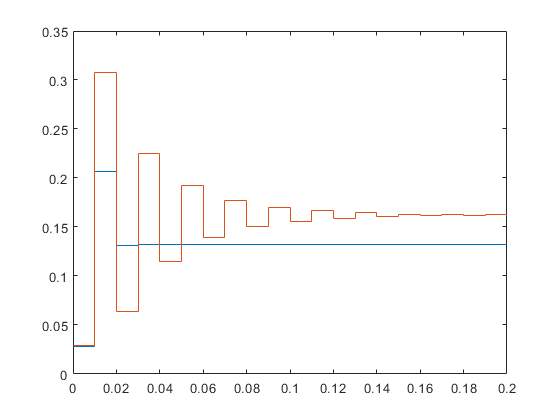


figure
stairs(0:T:0.2,muT3)
hold on
stairs(0:T:0.2,muT7c)